%clear();

%{
load("test_signal\sin1d0.mat");
Inp_sine = data{1}.Values.Data
Measure_sine = data{2}.Values.Data

TimeArr = data{1}.Values.Time

load("test_signal\ramp2d4.mat");
Inp_ramp = data{1}.Values.Data
Measure_ramp = data{2}.Values.Data

load("test_signal\pulse1d0.mat");
Inp_step = data{1}.Values.Data
Measure_step = data{2}.Values.Data

load("test_signal\stair1.mat");
Inp_stair = data{1}.Values.Data
Measure_stair = data{2}.Values.Data

load("test_signal\chirp2.mat");
Inp_chirp = data{1}.Values.Data
Measure_chirp = data{2}.Values.Data

Measure_test_signals = [
    Measure_sine;
    Measure_ramp;
    Measure_step;
    Measure_stair;
    Measure_chirp
];

save("test_signal\Test_Dataframe.mat")
%}

load("test_signal\Test_Dataframe.mat");

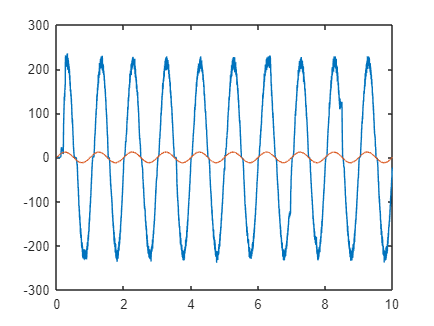

% Plot
figure(Name='Validation Testing Signal')
plot(TimeArr,Measure_sine,TimeArr,Inp_sine)

Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Store signals in arrays for easy iteration
Inp_test_signals = {Inp_sine, Inp_ramp, Inp_step, Inp_stair, Inp_chirp};
Measure_test_signals = {Measure_sine, Measure_ramp, Measure_step, Measure_stair, Measure_chirp};


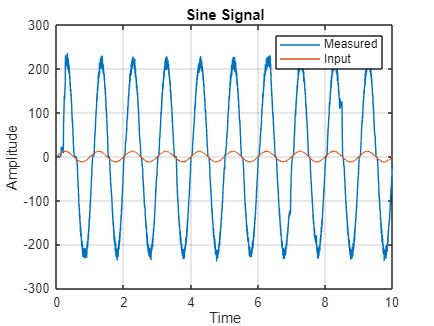

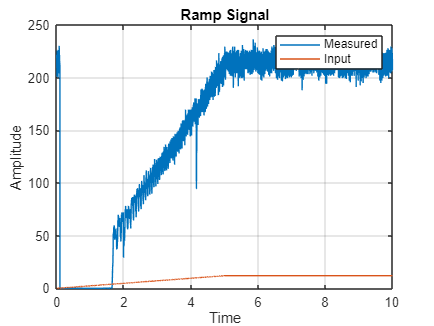

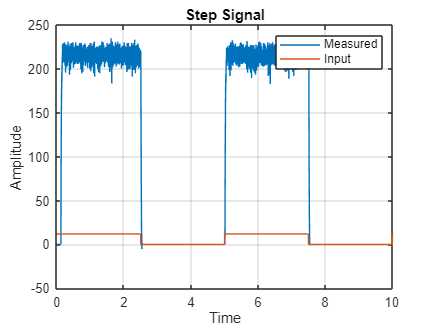

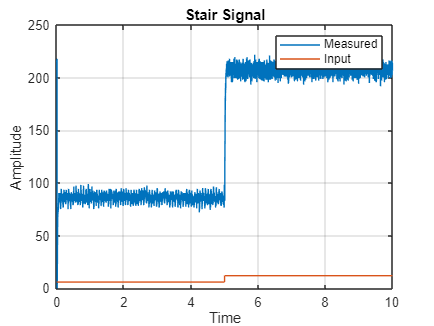

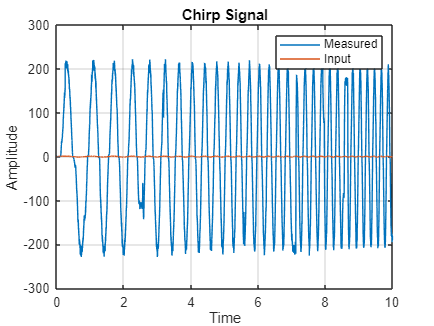


% Loop through each test signal and plot in a separate figure
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Signal']);
    plot(TimeArr, Measure_test_signals{i}, TimeArr, Inp_test_signals{i});
    title([Test_signal_names{i}, ' Signal']);
    legend('Measured', 'Input');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

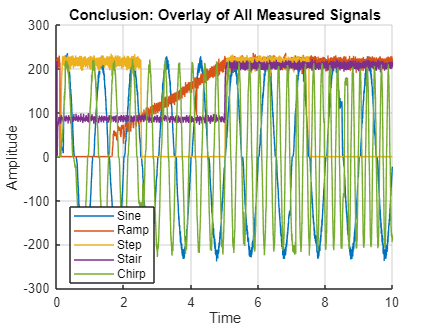


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Measured Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Measure_test_signals{i});
end
hold off;
title('Conclusion: Overlay of All Measured Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time');
ylabel('Amplitude');
grid on;

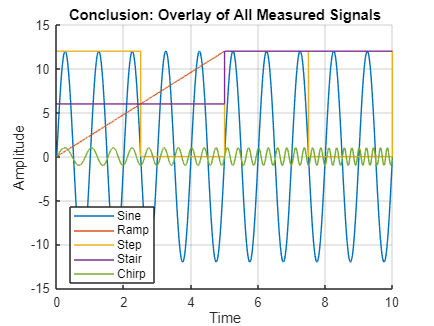


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Input Test Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Inp_test_signals{i});
end
hold off;
title('Conclusion: Overlay of All Measured Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time');
ylabel('Amplitude');
grid on;

load("model_predict\predict_sin01.mat");
%model_predict_signals = data.Data
model_predict_signals = {data.Data(:, 1), 
                        data.Data(:, 2),
                        data.Data(:, 3),
                        data.Data(:, 4),
                        data.Data(:, 5)}

model_predict_signals = 5×1 cell array
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}


## Plot input test, measure, predict and Compare

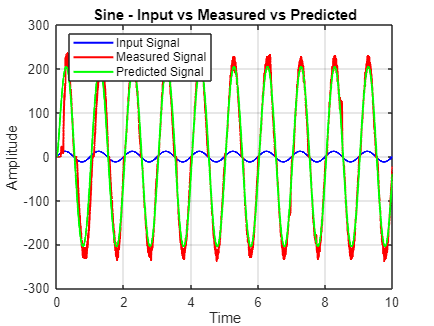

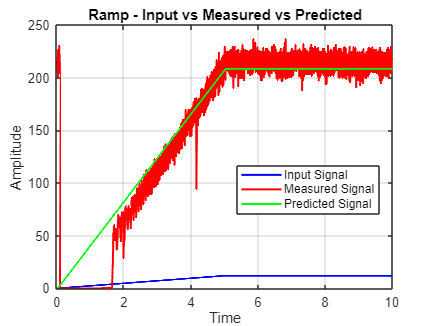

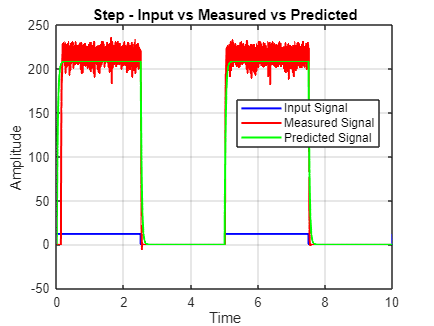

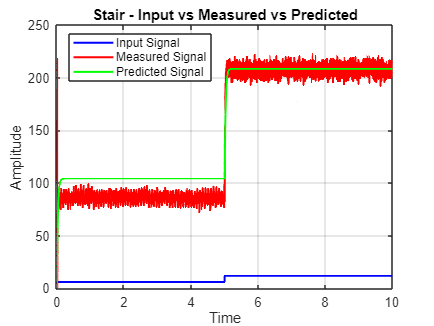

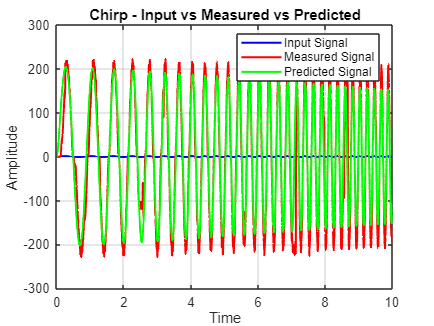


% Define colors for better visibility
colors = {'b', 'r', 'g'}; % Blue for input, Red for measured, Green for model prediction

% Loop through each test signal and plot with model predictions
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Comparison']);
    
    % Plot Input Test Signal
    plot(TimeArr, Inp_test_signals{i}, 'Color', colors{1}, 'LineWidth', 1.5);
    hold on;
    
    % Plot Measured Signal
    plot(TimeArr, Measure_test_signals{i}, 'Color', colors{2}, 'LineWidth', 1.5);
    
    % Plot Model Predicted Signal
    plot(TimeArr, model_predict_signals{i}, 'Color', colors{3}, 'LineWidth', 1.5);
    
    % Add Title and Legend
    title([Test_signal_names{i}, ' - Input vs Measured vs Predicted']);
    legend('Input Signal', 'Measured Signal', 'Predicted Signal', 'Location', 'best');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
    hold off;
end

% Function to compute R-squared
function R_squared = compute_rsquare(y_actual, y_pred)
    % Ensure input vectors are column vectors
    y_actual = y_actual(:);
    y_pred = y_pred(:);
    
    % Compute SSE (Sum of Squared Errors)
    SSE = sum((y_actual - y_pred).^2);
    
    % Compute SStot (Total Sum of Squares)
    SS_tot = sum((y_actual - mean(y_actual)).^2);
    
    % Compute R-squared
    R_squared = 1 - (SSE / SS_tot);
end

compute_rsquare(Measure_test_signals{1}, model_predict_signals{1})

ans = single
0.9710


% Compute R-squared for each signal type
R_squared_values = zeros(1, length(Test_signal_names));

fprintf('R-squared values for each test signal:\n');

R-squared values for each test signal:


for i = 1:length(Test_signal_names)
    R_squared_values(i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    fprintf('%s: %.4f\n', Test_signal_names{i}, R_squared_values(i));
end

Sine: 0.9710
Ramp: 0.8805
Step: 0.9610
Stair: 0.9406
Chirp: 0.9161
